# Demo 01: 3D CSI Phantom data

## data download and setup

add paths and set up data paths. Download phantom data (1.82 GB "phantom-DMI.tar.gz") from [zenodo.org (DOI: 10.5281/zenodo.14652737)](https://doi.org/10.5281/zenodo.14652737).

% add all dependencies
addpath(genpath('/ptmp/pvalsala/Packages/mapVBVD'))
addpath(genpath('/ptmp/pvalsala/Packages/DeuteMetCon'))
addpath(genpath('/ptmp/pvalsala/Packages/OXSA'))

% data path
sn='/ptmp/pvalsala/deuterium/dataForPublication/phantom-DMI';
dirst_csi=dir(fullfile(sn,"*rpcsi_fid*.dat"));


## load metabolite structure 

The chemical shifts, measured relaxation times and labels of all four metabolites in phantom is organised in a array of struct

% second argument is the frequency offset of water in Hz
metabolites=getMetaboliteStruct('phantom',0);


## `Inputs and flags for metabolite mapping`

`All functions and data required for all data processing steps like image reconstruciton, coil combination and spectral seperation were encapsualted in a single class `MetCon_CSI.m`. All inputs and flags except the raw data file is a name-value pair as described below.`

% | name                        | description                                                | default   | possible options                                                 |
% |-----------------------------|------------------------------------------------------------|-----------|------------------------------------------------------------------|
% | 'metabolites'               | struct array with definition of metabolites                | []        | see getMetaboliteStruct.m function                               |
% | 'fm'                        | 1H fieldmap in rad/s                                       | []        | 3D numeric matrix or 'IDEAL'                                     |
% | 'csm'                       | coil maps                                                  | []        | 3D numeric matrix                                                |
% | 'mask'                      | mask for spectral separation                               | []        | 3D logical matrix                                                |
% | 'doDenosing'                | SVD denoising                                              | 0         | scalar No of components, -1 for debug                            |
% | 'Solver'                    | spectral separation method                                 | 'IDEAL'   | {'phaseonly','pinv','IDEAL','IDEAL-modes','AMARES','LorentzFit'} |
% |                             |                                                            |           | 'phaseonly'- linear method with only phase evolution             |
% |                             |                                                            |           | 'pinv'- linear method with full signal model                     |
% |                             |                                                            |           | 'IDEAL'- iterative IDEAL algorithm                               |
% |                             |                                                            |           | 'IDEAL-modes'-IDEAL algorithm for phase cycled data              |
% |                             |                                                            |           | 'AMARES'- AMARES spectral fitting                                |
% |                             |                                                            |           | 'LorentzFit'- lorentzian spectral fitting                        |
% | 'parfor'                    | flag to use parfor                                         | true      | boolean                                                          |
% | 'doZeroPad'                 | zero pad factor                                            | [1 1 1 0] | positive scalar array [3 physical axis x 1 time]                 |
% | 'doSmoothFM','maxit'        | IDEAL flags: fieldmap smooth factor and maximum iterations | 1,10      | scalar(+ve: gaussian, -ve: median),postive scalar                |
% | 'doPhaseCorr'               | phase correction mode                                      | 'none'    | {'none','Manual','Burg'}                                         |
% | 'CoilSel','PCSel','EchoSel' | arrays to picks some of coils, time points and phasecyles. | 1:max()   | positive integer array                                           |
% |'doNoiseDecorr'              | flag to perform noise decorrelation                        | true      | boolean                                                          |
% | 'doCoilCombine'             | coil combine mode                                          | 'adapt1'  | {'none','sos','adapt1','wsvd'}                                   |

CSI_setting={'metabolites',metabolites,'doPhaseCorr','none','parfor',true,...
    'doCoilCombine','adapt1','doZeropad',[0.5 0.5 0.5 0],'mask',[],'Solver','IDEAL','fm',[]};

## Process data

CSI_filename=fullfile(sn,dirst_csi(end).name);
mcobj_csi=MetCon_CSI(CSI_filename,CSI_setting{:});

Software version: VD (!?)
Reader version: 1660732089 (UTC: 17-Aug-2022 10:28:09)
Scan 1/1, read all mdhs:
   661.3 MB read in   10 s
Using T2* =20 ms 
starting reco
initial CSI data size:           10   25   25   25  256
final CSI data size:           10   51   51   51  256
reco  time =   19.8 s
estimating field map(1/2) 
estimating metabolities(2/2) 
Metabolite mapping time =   26.8 s


### Plotting

After image reconstruciton and spectral seperation, metbolite amplitudes are store in mcobj_csi.Metcon. The 4D Metcon matrix and 2H field map estimated by IDEAL algorithm can be quickly visualized with `PlotResults` method.

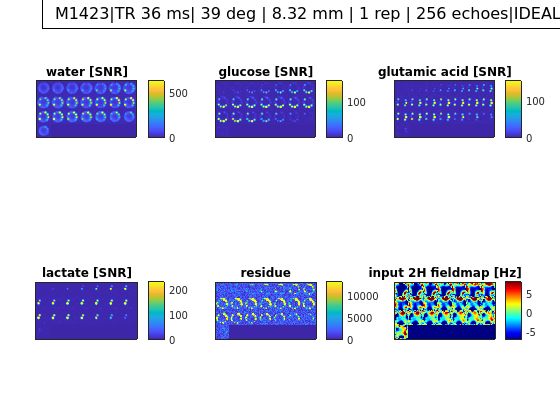

mcobj_csi.PlotResults()

## Data structure of Metcon_CSI object

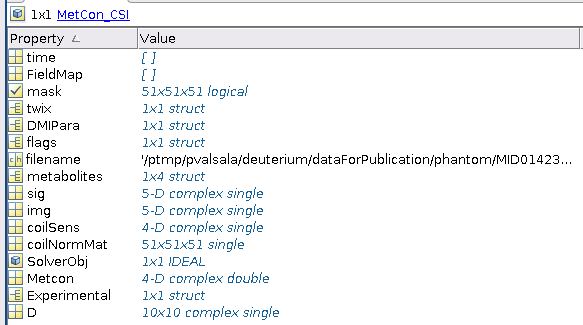

 Where 

- DMIPara are the important sequence parameters parsed from twix with `getDMIPara.m` fucntion

- flags contains all the processing flags

- sig - averaged signal [CHAx LIN  xSEG x PAR   x COL (time) x REP(PhaseCylces)]

- img - reconstructed image [CHA x 3 physical dimension x time]

- Metcon - Metabolite amplitudes [CHA x 3 physical dimension x time]

- Experimental- contains all experimental outputs of processing (fieldmap, residue, other fit parameters, fit quality)

- D- noise decorrelation matrix.

## Processing CSI-bSSFP data

We use `IDEAL-modes` for phase-cycled data for SNR optimallity. Other Solver flags use averaged phase-cyles volumes

CSI_setting_ssfp={'metabolites',metabolites,'doPhaseCorr','none','parfor',true,...
     'doCoilCombine','adapt1','doZeropad',[0.5 0.5 0.5 0],'mask',[],'Solver','IDEAL-modes','fm','IDEAL'};
dirst_csi_ssfp=dir(fullfile(sn,"*rpcsi_ssfp*.dat"));
CSI_filename=fullfile(sn,dirst_csi_ssfp(end).name);
mcobj_ssfp=MetCon_CSI(CSI_filename,CSI_setting_ssfp{:});

Software version: VD (!?)
Reader version: 1660732089 (UTC: 17-Aug-2022 10:28:09)
Scan 1/1, read all mdhs:
   335.9 MB read in   10 s
Using T2* =20 ms 
starting reco
initial CSI data size:           10  25  25  25  64   4
final CSI data size:           10  51  51  51  64   4
reco  time =   17.7 s
estimating field map(1/2) 
estimating metabolities(2/2) 
Metabolite mapping time =   25.1 s


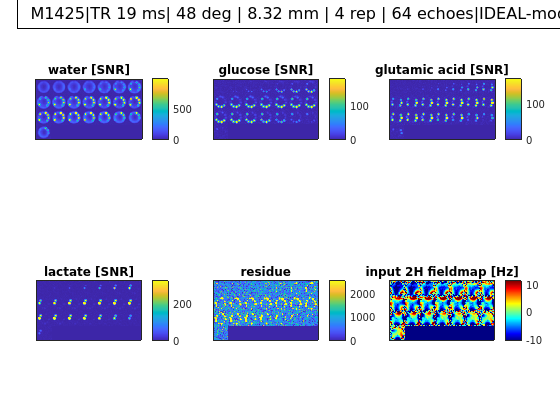

mcobj_ssfp.PlotResults()

## Other miscallaneous methods which can be useful

Using T2* =20 ms 


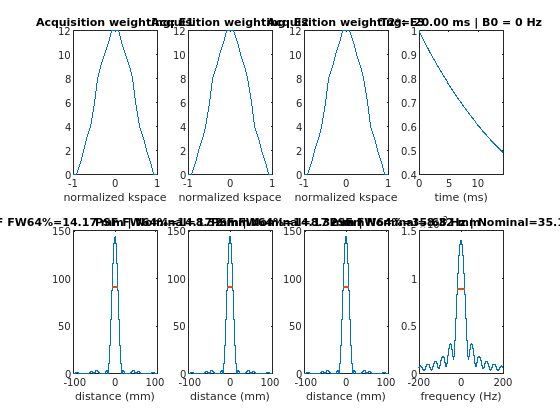

% The metabolite amplitudes can be normalized into SNR 
metcon_SNR= mcobj_csi.getNormalized();

% method and quantified into mM with 10 mM water reference using `getmM`
% fucntion. (Doesn't work in phantom as 10mM water reference is not there!)
metcon_mM= mcobj_csi.getmM();

% export NIFTI volumes of all outputs (average image, metabolite amplitude in SNR unit and mM)
pn=fullfile(sn,'proc',sprintf('CSI_%s',datetime('today','Format','yyyyMMMdd')));
mkdir(pn);cd(pn);
niiFileName=mcobj_csi.WriteImages(pn);

%plot the k-space weighting and PSF to get realistic voxel size (FW64%)
voxel_size_mm= getPSF_CSI(mcobj_csi.twix);

% it is non-sense for phantom scans but still!
Intake_time_mins=mcobj_csi.getMinutesAfterIntake('08:00');


### Debug (only for AMARES and Lorentzian solver so far)

Useful for checking data at a particular voxel index. [15,14,25] is the voxel with all metabolites.

Iterations = 36.
Norm of residual = 770.811
Norm of the data = 62474.292
resNormSq / dataNormSq = 0.012
zeroOrderPhaseRad = 2.222
    chemShift: [0.0474 -1.0161 -2.4680 -3.4884]
    linewidth: [2.0000 11.2813 4.7048 2.2230]
    amplitude: [34.5440 11.3873 8.7223 14.5698]
        phase: [127.3026 127.3026 127.3026 127.3026]
        sigma: [0 0 0 0]

Performing Nlorentz fit


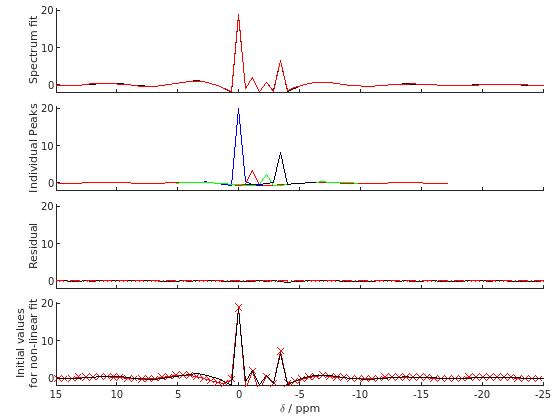

Fitting stopped because the number of iterations or function evaluations exceeded the specified maximum.


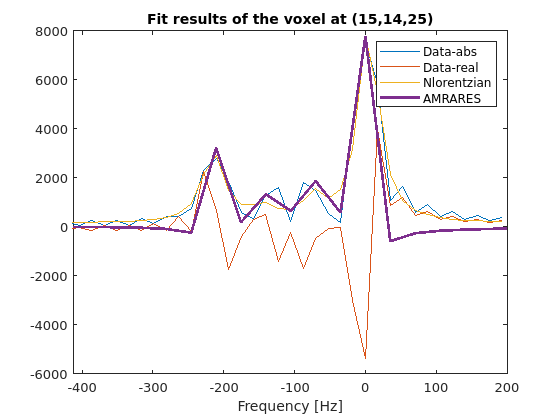

mcobj_csi.demoFit([15,14,25])